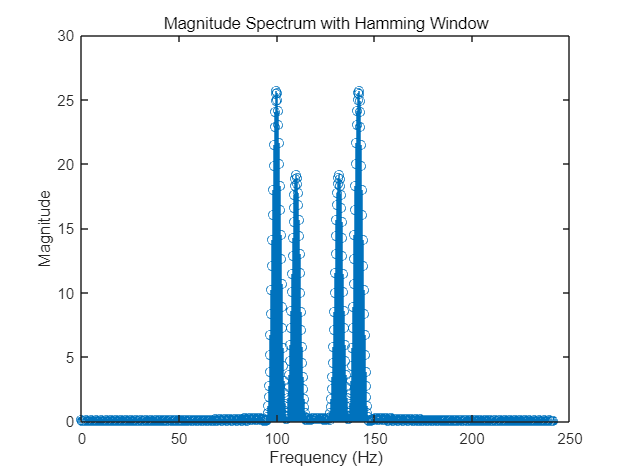


f1 = 100; 
f2 = 110; 
T = 0.4;  

fsam = 2.2 * max(f1, f2); 

t = 0:1/fsam:T-1/fsam; 

x_t = cos(2*pi*f1*t) + 0.75*cos(2*pi*f2*t);

window = hamming(length(t))';
x_t_windowed = x_t .* window;

N = 1024;
X_f = fft(x_t_windowed, N);

f = (0:N-1)*(fsam/N);

figure;
stem(f, abs(X_f));
title('Magnitude Spectrum with Hamming Window');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

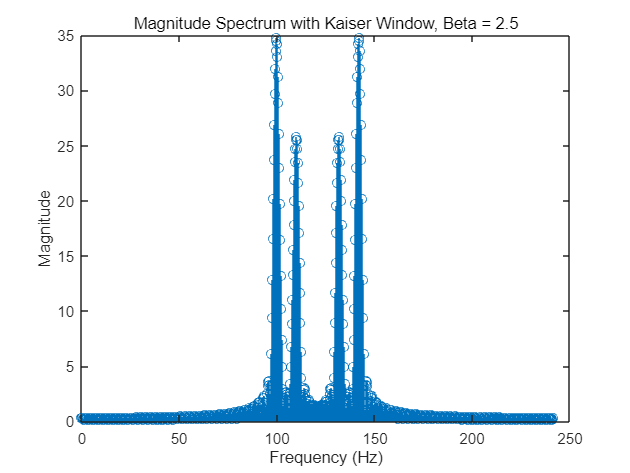

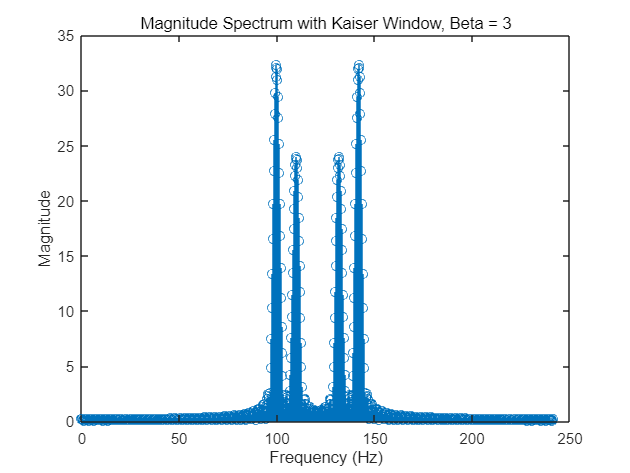

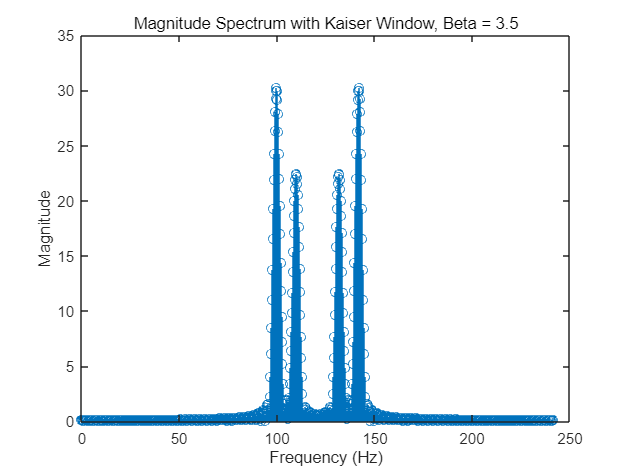

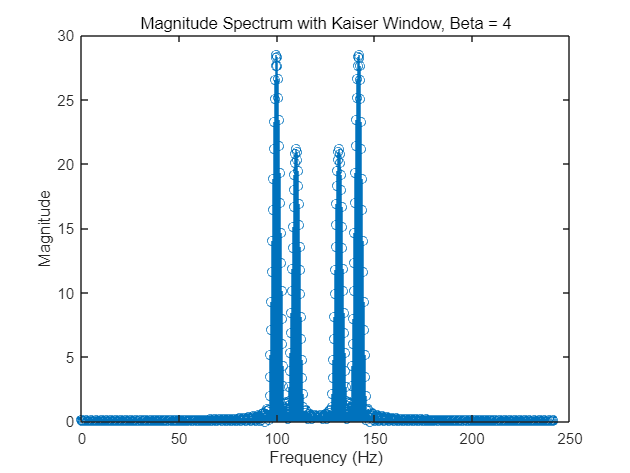

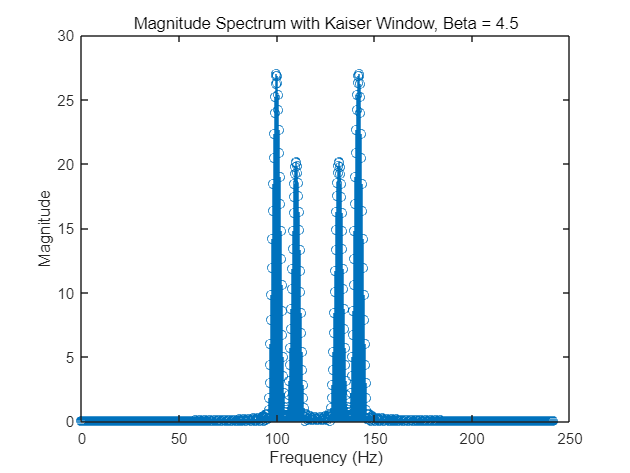

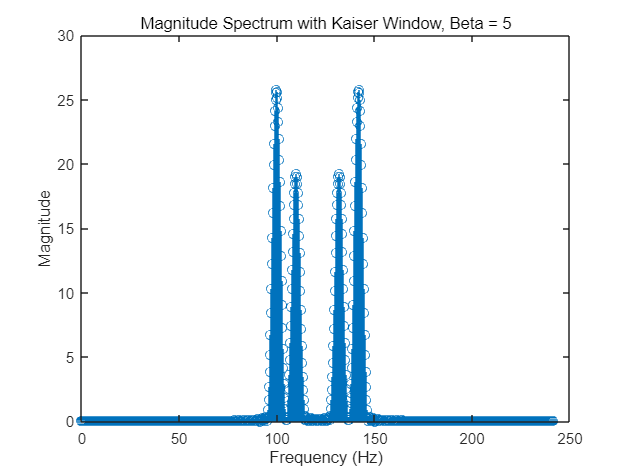


beta_values = [2.5, 3, 3.5, 4, 4.5, 5]; 
for beta = beta_values
    kaiser_window = kaiser(length(t), beta)';
    x_t_kaiser_windowed = x_t .* kaiser_window;
    X_f_kaiser = fft(x_t_kaiser_windowed, N);

    figure;
    stem(f, abs(X_f_kaiser));
    title(['Magnitude Spectrum with Kaiser Window, Beta = ', num2str(beta)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end

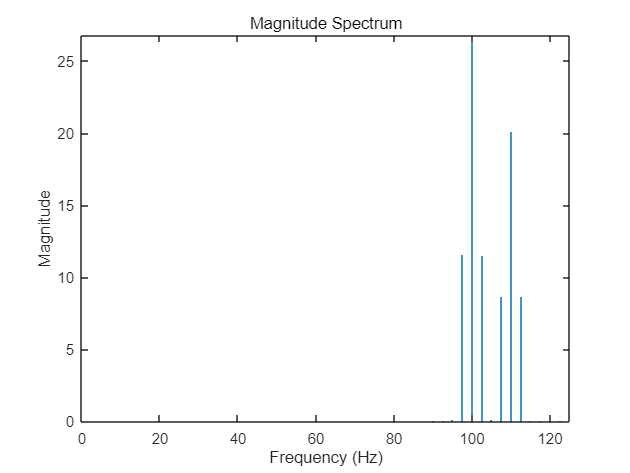

f1 = 100; 
f2 = 110; 

fsam = 250; 
Ts = 1/fsam; 
T = 0.4; 

t = 0:Ts:T-Ts;

x_t = cos(2*pi*f1*t) + 0.75*cos(2*pi*f2*t);

windowed_signal = x_t .* hamming(length(t))';

N = length(windowed_signal); 
X_f = fft(windowed_signal, N);


f = (0:N-1)*(fsam/N);

figure;
stem(f, abs(X_f), 'Marker', 'none');
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
axis([0 fsam/2 0 max(abs(X_f))]); 